# BFSK変復調システム

前提条件

- AWGN通信路

- SN比: 0dB

- 搬送波周波数: 2kHz

- サンプリング周波数: 40kHz

## ワークスペースの初期化

clear
close all
clc

## 図のフォント設定

set(0, 'defaultAxesFontSize', 14);
set(0, 'defaultAxesFontName', 'times');
set(0, 'defaultTextFontSize', 14);
set(0, 'defaultTextFontName', 'times');

## パラメータの設定

BANDWIDTH = 2e3;
CARRIER_FREQ = 2e3;
MULTIPLE_LEVEL = 2;

snRatio = 0;

samplingFreq = 20*CARRIER_FREQ;
samplingPeriod = 1/samplingFreq;

timePeriod = 1/BANDWIDTH;
bitsPerSymbol = log2(MULTIPLE_LEVEL);

freqSeparation = 10;
samplesPerSymbol = floor(timePeriod/samplingPeriod);

t = 0:1/samplingFreq:timePeriod-1/samplingFreq;

## 入力ビット列の確認

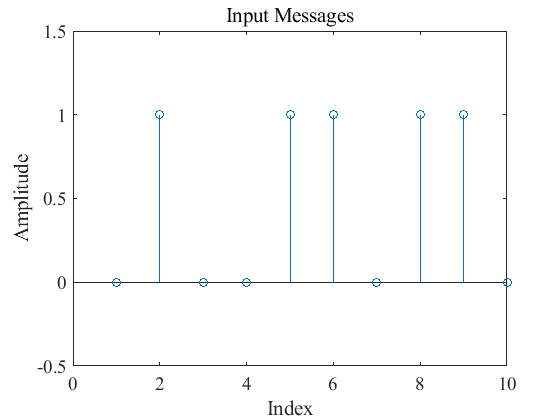

messages = [0 1 0 0 1 1 0 1 1 0];

stem(messages)
ylim([-0.5 1.5])
title('Input Messages')
xlabel('Index')
ylabel('Amplitude');

## 変調信号の確認

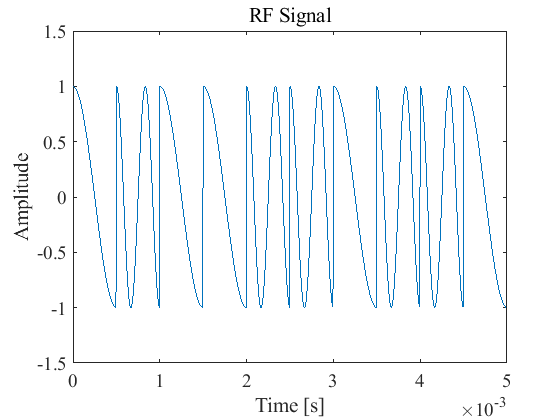

infoBinaryTilde = reshape(messages, [bitsPerSymbol,round(length(messages)/bitsPerSymbol)]);
infoBinary = infoBinaryTilde';

alpha1 = -1;
tt = 0:1/samplingFreq:length(infoBinary)*timePeriod-1/samplingFreq;

alpha2 = 1;
for k = 1:size(messages, 2)
    bit = infoBinary(k,1);
    if bit == 0 
        u(k) = alpha1;
    elseif bit == 1
        u(k) = alpha2;
    end
end
freqDelta = 1e3;

signalRF =  zeros(1, size(infoBinary,2)*size(t,2));
for k = 1:length(infoBinary)
    signalRF(1+(k-1)*size(t,2):k*size(t,2)) = cos(2*pi*(CARRIER_FREQ+u(k)*freqDelta)*t);
end

plot(tt, signalRF)
ylim([-1.5 1.5])
title('RF Signal')
xlabel('Time [s]')
ylabel('Amplitude')

## 雑音印加後の信号確認

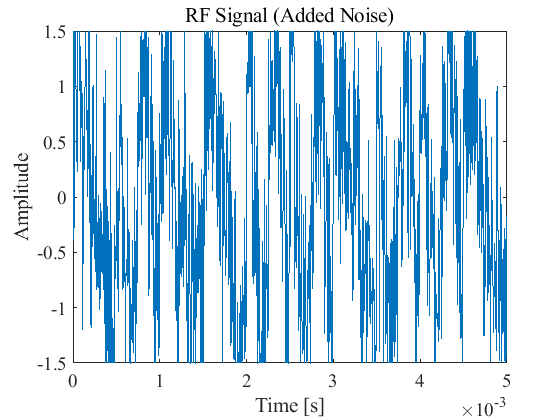

rng('shuffle')
signalAddedNoise = awgn(signalRF, snRatio, 'measured');  % signalAddedNoise = signalRF;

plot(tt, signalAddedNoise)
ylim([-1.5 1.5])
title('RF Signal (Added Noise)')
xlabel('Time [s]')
ylabel('Amplitude')

## 出力ビット列の確認

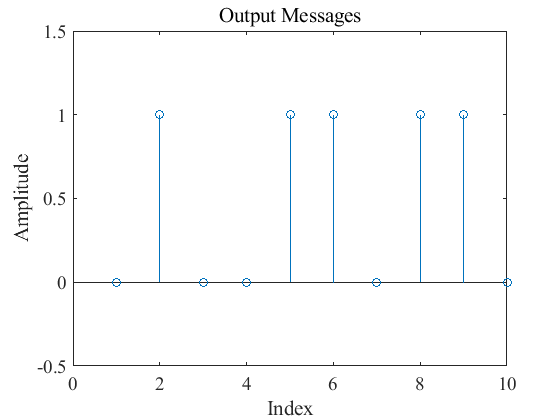

z1 = zeros(1, size(infoBinary, 2));
z2 = zeros(1, size(infoBinary, 2));
z3 = zeros(1, size(infoBinary, 2));
z4 = zeros(1, size(infoBinary, 2));
for k = 1:length(infoBinary)
    z1(k) = sum(signalAddedNoise(1+(k-1)*size(t,2):k*size(t,2)).*sin(2*pi*(CARRIER_FREQ+alpha1*freqDelta)*t))*(2/(timePeriod*samplingFreq));
    z2(k) = sum(signalAddedNoise(1+(k-1)*size(t,2):k*size(t,2)).*cos(2*pi*(CARRIER_FREQ+alpha1*freqDelta)*t))*(2/(timePeriod*samplingFreq));
    z3(k) = sum(signalAddedNoise(1+(k-1)*size(t,2):k*size(t,2)).*sin(2*pi*(CARRIER_FREQ+alpha2*freqDelta)*t))*(2/(timePeriod*samplingFreq));
    z4(k) = sum(signalAddedNoise(1+(k-1)*size(t,2):k*size(t,2)).*cos(2*pi*(CARRIER_FREQ+alpha2*freqDelta)*t))*(2/(timePeriod*samplingFreq));
end

recievedMessages = zeros(1, size(infoBinary, 2));
for k = 1:length(infoBinary)
    if z1(k)^2+z2(k)^2 >= z3(k)^2+z4(k)^2
        recievedMessages(k) = 0;
    elseif z1(k)^2+z2(k)^2 < z3(k)^2+z4(k)^2
        recievedMessages(k) = 1;
    end
end

stem(recievedMessages)
ylim([-0.5 1.5])
title('Output Messages')
xlabel('Index')
ylabel('Amplitude')

## ビット誤り率の確認

bitErrorRate = biterr(messages, recievedMessages)/length(messages)

bitErrorRate = 0